# Worksheet 4, Part 2 / 4: Modeling with Matrices

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 4 comes to you in **four parts**; `worksheet4_part1.mlx`, `worksheet4_part2.mlx`, `worksheet4_part3.mlx`, and `worksheet4_part4.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to represent a system of multiple equations using a matrix.

- How to represent social connectivity using matrices.

- How to compute metrics of matrix-valued states.

- Integrate these ideas to run and interpret an **agent-based model**.

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `infected.csv`

- `simulate_absir.m`

clear;

## Infection Exposure and Social Connections

In the previous part of the worksheet, we introduced the vectors `v_infect` and `v_recover` to update which individuals become infected and which recover from the disease. But how do we get these vectors?

Our model for` v_recover` will be straightforward: At every timestep of the simulation, every person will have a chance to recover from the disease. However, with `v_infect` we will use a more detailed model that considers the **social connections** among all members of the population. Crucially, in our agent-based model, a person will have a chance to be infected *only* if they are socially connected to someone who already has the disease.

To start thinking about this, let's first consider a population with only two people. If exposure to an infected person *guaranteed* infection (more on that in a bit...), then we could write `v_infect` in terms of the following set of equations:


$$v_{1, \text{infect}} = I_2 \\
v_{2, \text{infect}} = I_1$$


For instance, if Individual 2 is infected, then the infection vector `v_infect` will be:

Iv = [0; 1]

Iv =      0
     1


v_infect = [Iv(2); Iv(1)]

v_infect =      1
     0


This set of equations has a particular structure, which you'll think about in the next exercise.

### Exercise 1 / 10

Answer the following question:

Why doesn't $v_{1, \text{infect}}$ depend on $I_1$?

- *(Write your answer here)*

Whether or not person 1 is infected won't affect whether or not they become infected. They're already infected, they can't be infected 2 times in a row.

Writing out the equations for `v_infect` is straightforward enough with a small population, but this will quickly grow unwieldy if we have a large population. (Imagine if we had 100 people in our model!) Our goal is to re-write this pair of equations in terms of a matrix-vector product


$$\vec{v}_{\text{infect}} = M \vec{I}$$


I find it helpful to expand each equation with coefficients for all vector entries, as this makes it easier to see the matrix structure


$$v_{1, \text{infect}} = 0 I_1 + 1 I_2 \\
v_{2, \text{infect}} = 1 I_1 + 0 I_2$$


From this expression, we can directly read the entries in the matrix:


$$M = \left[\begin{array}{cc} 0 & 1 \\ 1 & 0 \end{array}\right]$$


Let's practice translating from a set of equations into a matrix.

### Exercise 2 / 10

Translate the following equations


$$\begin{array}{l}
v_{1,\;\textrm{infect}} =I_2 +I_3 \\
v_{2,\textrm{infect}} =I_1 +I_3 \\
v_{3,\textrm{infect}} =I_1 +I_2 
\end{array}$$


into the matrix-vector equation


$$\vec{v}_{\text{infect}} = M \vec{I}$$


To do this, you will need to find the matrix `M` that makes the last expression true.

*Hint: *First, re-write the set of equations with coefficients in order to "see" the matrix M.

% TODO: Construct the matrix M
M = [0, 1, 1; 1 0 1; 1 1 0]

M =      0     1     1
     1     0     1
     1     1     0



% NOTE: Do not edit these lines; 
% use this to check your work
assert(all(diag(M) == 0), 'The diagonal of M should be zeros')
assert(sum(M, 'all') == 6, 'The matrix M should have 6 nonzero entries')
disp('Assertions passed!')

Assertions passed!


Matrices will help us represent very large systems of equations. We can inspect the values of the matrix, but larger matrices will require visualization to feasibly make sense of their structure.

### Exercise 3 / 10

Visualize the matrix `M` that you defined above.

*Hint:* We learned how to visualize matrices in the previous part of Worksheet 4!

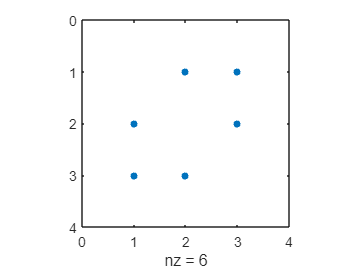

% TODO: Visualize M
spy(M)

How does the visualization of the matrix relate to the *social connectivity* between the three individuals in the model?

- *(Write your response here) *Person 1 was the first person to be infected and they were in contact with person 2 who spread it to person 3.

We can read the structure of social connectivity by directly inspecting the matrix `M`, as you'll practice below.

### Exercise 4 / 10

Use the matrix below to answer the following questions.

% Use this matrix to answer the following questions
M = [
    0  1  0  1;
    1  0  0  0;
    0  0  0  0;
    1  0  0  0
]

M =      0     1     0     1
     1     0     0     0
     0     0     0     0
     1     0     0     0


Translate this matrix back into a set of four equations for `v_infect`. Who can infect Individual 1? Who can infect Individual 3?

- *(Write your response here; you may need multiple lines)*

v1_infect = I2 + I4

v2_infect = I1

v3_infect = 0

v4_infect = I1

### Constructing Matrices

We could construct these `M` matrices by hand, but that would be very tedious (and error prone!), especially for larger populations. In order to make studying larger populations feasible, let's learn how to use a few matrix construction tools to build up `M` quickly.

The function `ones()` makes a matrix filled entirely with ones:

% Matrix of ones
ones(4, 4)

ans =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


The function `eye()` makes a matrix with ones along the diagonal *only*. (This is called the identity matrix.)

% Identity matrix
eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Using these two functions, it is possible to build a matrix `M` that represents all individuals in a population connected to each other (but not themselves). You'll figure out how to do this in the next exercise.

### Exercise 5 / 10

Use the functions `ones()` and `eye()` to build a matrix M that represents all six people in a population mutually connected.

% TODO: Construct the matrix M
M = ~eye(6)% Replace this code with the appropriate math

M = 6×6 logical array
   0   1   1   1   1   1
   1   0   1   1   1   1
   1   1   0   1   1   1
   1   1   1   0   1   1
   1   1   1   1   0   1
   1   1   1   1   1   0



% NOTE: Do not edit these lines; 
% use this to check your work
assert(all(diag(M) == 0), 'The diagonal of M should be zeros')
assert(sum(M, 'all') == 30, 'The matrix M should have 30 nonzero entries')
disp('Assertions passed!')

Assertions passed!


## Verification

Verification is the process of checking that we have implemented the model correctly. This is a crucial step of building a model, as we can easily make mistakes in translating our ideas about the model into code. To verify our implementation of the agent-based SIR model, we will use the following fact:

- At any given time, an individual can only be Susceptible, Infected, or Recovered (exclusively).

Since we represent the S, I, R as boolean vectors, we can translate the fact above into a mathematical statement


$$S + I + R = 1$$


Note that this statement should also hold for the vectors we use in the model:

% Define an example state
Sv = [0; 1; 1];
Iv = [1; 0; 0];
Rv = [0; 0; 0];

% Check the sum
Sv + Iv + Rv

ans =      1
     1
     1


Likewise, the summation should hold for the entire state history of the model.

### Exercise 6 / 10

Use the verification "fact" above to find the *mistakes* in the following State history matrices. Answer the questions below.

% Define the state history as matrices
Sh = [
    1 1 1 1;
    1 1 1 1;
    1 0 0 0;
];
Ih = [
    1 1 1 1;
    0 0 0 0;
    0 1 1 0;
];
Rh = [
    0 0 0 0;
    0 0 0 0;
    0 0 0 0;
];

% TODO: Use the ideas of verification to figure out where
% things went wrong in the model that generated this data

Where are the errors in the state history? (Which states, and in which timesteps?)

*Hint:* There are two errors that span different lengths of time.

- *(Write your response here) *Everyone is in both the susceptible stock and the infected stock at the beginning. 

- *(Write your response here) *At the end person 4 is in no stock.

## The Full Model

Using the ideas discussed above, we can define an agent-based SIR model! The code in `simulate_absir.m` implements the model with some additional tweaks:

- The full model generates `v_infect` randomly. This is because being exposed to an infected individual does not guarantee that one will become infected.

- The full model generates `v_recover` randomly. This is to model variation in recovery time among individuals.

- The full model takes `infection_rate` and `recovery_rate` parameters to adjust the relevant effects for all individuals in the model.

We'll discuss the importance and implications of *randomness *in models in much greater detail in Worksheet 5 / Project 3. For now we'll focus on the differences between modeling the population as a stock and modeling the population as individuals (agents).

### Exercise 7 / 10

The following code will run the full model with a matrix defining the connections between members of the population. Generate a matrix `M` that represents a population where everyone is connected to everyone.

% Study a population of 100 people over 150 timesteps
n_population = 100;
n_time = 150;

% TODO: Set up the appropriate matrix
M = ~eye(n_population,n_population); % Fix this

% NOTE: Do not edit these lines; 
% use this to check your work
assert(all(diag(M) == 0), 'The diagonal of M should be zeros')
assert(sum(M, 'all') == 1e4 - 100, 'The matrix M should have 9900 nonzero entries')
disp('Assertions passed!')

Assertions passed!



% Set up the initial Infected state
Iv1 = zeros(n_population, 1);
Iv1(1) = 1;

% Run the simulation
[Sh, Ih, Rh] = simulate_absir(M, Iv1, n_time, 0.5, 0.05);

Once you've successfully run the model, visualize the results in the next exercise.

### Exercise 8 / 10

Visualize and interpret the infection history `Ih` from the full model. Answer the questions below.

*Hint*: We learned how to visualize a matrix above.

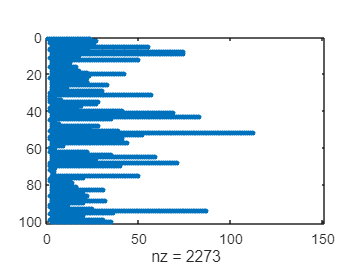

figure(); clf;
% TODO: Visualize Ih here
spy(Ih)

Does this model exhibit the kind of infection peak we're used to seeing with the compartmental SIR model?

- *(Write your answer here) *No, instead of one peak, there are multiple peaks, and there aren't many bars that are close in length.

Do all the infections last the same length of time? How can you tell?

- *(Write your answer here) *No, because each bar is a different length.

What about the structure of the results `Ih` makes this more difficult to interpret, as compared with the compartmental SIR model?

- *(Write your answer here) *With the SIR model you assume every infection lasts the same amount of time and assume everyone is interacting with everyone else. Here each person's infection lasts a different amount of time, meaning it is more difficult to see how many people are infected at once.

## Metrics

The state of the agent-based SIR model is quite complex and difficult to interpret, as we saw above. This means that it is even more important that we define sensible **Metrics** to help make sense of the results. To finish up this worksheet we'll start thinking about how to derive meaningful summaries from the agent-based SIR model to use as metrics.

### Exercise 9 / 10

Compute the total number of infected persons based on the current state `Iv`.

% Agent-based state of Infected
Iv = [0; 1; 1; 0; 0; 0];

% TODO: Compute the total number of infected persons based on Iv
I = sum(Iv); % FIX THIS

% NOTE: Do not edit these lines; 
% use this to check your work
assert(I == sum(Iv), 'Incorrect value!')
disp('Assertions passed!')

Assertions passed!


Next, you'll apply this idea to summarize the *infection history* from the model.

### Exercise 10 / 10

Look up the documentation for the function sum`()`; use this to compute the total number of Infected persons from `Ih` at every timestep in the simulation. Answer the questions below.

*Hint:* You will need to take the summation along a specific dimension; look for the argument `DIM`.

% TODO: Compute the total number of infected at each timestep
%A = 1:length(n_time)
I_count_history = sum(Ih,1) % FIX THIS CODE

I_count_history =      1    31    93    93    89    86    82    81    75    72    71    69    67    61    60    60    55    55    53    52    47    46    40    37    36    35    34    31    29    29    28    26    25    24    24    20    19    19    19    18    17    15    14    14    13    13    13    13    13    13




% NOTE: Do not edit these lines; 
% use this to check your work
assert(length(I_count_history) == n_time, 'Your I_count_history does not have the correct number of entries.')
disp('Assertions passed!')

Assertions passed!


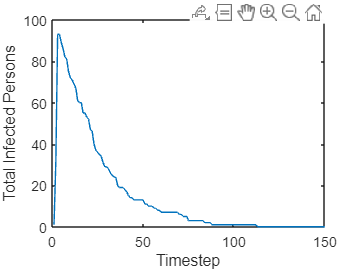


% This will visualize the results
figure(); clf;
plot(I_count_history)
xlabel('Timestep')
ylabel('Total Infected Persons')

Does this model exhibit the kind of infection peak we're used to seeing with the compartmental SIR model? Is it easier or harder to answer this question, as compared with using the `spy()` plot we used above?

- *(Write your answer here) *Yes, because it's easier to tell how many people are infected at a given time.

Do all the infections last the same length of time? Is it *possible *to answer this question, based on this figure?

- *(Write your answer here) *No, it's not possible because the figure doesn't specify exactly who is infected at each time.

### Example

We can further process the data to derive other useful quantities. For instance, we can compute the `max()` over the data to determine the maximum number of infected individuals, and when this maximum occurs. These are examples of **scalar metrics**; single-number summaries from the model that focus in on highly-specific pieces of information.

% Compute the max number of infected, and when this occurs
[I_max, t_max] = max(sum(Ih, 1))

I_max = 93

t_max = 3

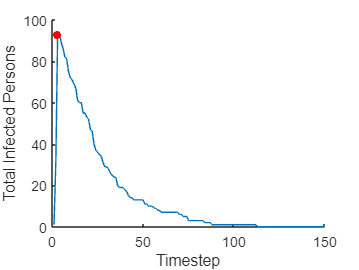


% Visualize on the infection history
figure(); clf; hold on;
plot(I_count_history)
plot(t_max, I_max, 'r.', 'MarkerSize', 16)
xlabel('Timestep')
ylabel('Total Infected Persons')

### Example

Scalar metrics are particularly useful when combined with a **parameter sweep**. It would be totally infeasible to plot the full model State history against a swept parameter value. However, if we can choose a meaningful Metric to summarize the model's results

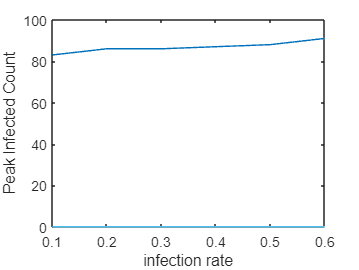

% The following code performs a parameter sweep over the infection_rate

% Define the set of parameter values for the sweep
n_sweep = 6;
Infection_rate_values = linspace(0.1, 0.6, n_sweep);
% Reserve space for the output values
I_max_values = zeros(n_sweep);
t_max_values = zeros(n_sweep);

% Loop over all infection_rate values
for i = 1 : n_sweep
    % Select the desired infection_rate
    infection_rate = Infection_rate_values(i);
    % Run the simulation
    rng(101)
    [Sh, Ih, Rh] = simulate_absir(M, Iv1, n_time, infection_rate, 0.05);
    % Compute the chosen metrics
    [I_max, t_max] = max(sum(Ih, 1));
    % Store the values
    I_max_values(i) = I_max;
    t_max_values(i) = t_max;
end

% Visualize the count of Infected at the peak
figure(); clf;
plot(Infection_rate_values, I_max_values)
xlabel('infection rate')
ylabel('Peak Infected Count')

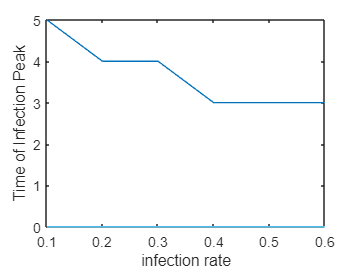


% Visualize the timestep of the peak infection count
figure(); clf;
plot(Infection_rate_values, t_max_values)
xlabel('infection rate')
ylabel('Time of Infection Peak')

Later in Worksheet 4, we'll discuss metrics further. In particular we'll discuss how metrics should be carefully chosen to support our modeling question.

## Looking Forward

Matrices are the mathematical tool we use to implement our social connectivity models. However, it will be easier to think about (and hence work with) social connectivity data if we have a *graphical* way of interpreting these scenarios. Next time we'll learn the fundamentals of *graph theory* to help with modeling social networks.